close all
clear variables

% % Definición de las constantes del sistema
% k = 1;     % Constante del resorte (N/m)
% m = 1;      % Masa (kg)
% b = 0;
% Ts = 0.01;
% 
% x0 = randn();   % Posición inicial de la masa (m)
% v0 = randn();     % Velocidad inicial de la masa (m/s)
% 
% 
% A = [0 1; -k/m -b/m];
% B = [0 1/m]';
% C = [1 0];
% D = 0;
% 
% sys = ss(A,B,C,D);
% 
% % Definición de la función que describe el sistema
% fun_sys = @(x, u) A*x + B*u;
% 
% % Definición del tiempo de simulación
% tspan = 0:Ts:50;
% 
% % Definición de las condiciones iniciales
% x0 = [x0; v0];
% u = 0;
% % Solución de la ecuación diferencial
% [t, x] = ode45(@(t,x) fun_sys(x, u), tspan, x0);
% 
% p = -m*x(:,2);
% q = x(:,1);
% 
% % Parámetros del ruido
% mu = 0;         % media
% sigma = 0.00;    % desviación estándar
% 
% % Generar ruido gaussiano
% noise_q = mu + sigma * randn(size(q));
% noise_p = mu + sigma * randn(size(p));
% 
% q_noisy = q + noise_q;
% p_noisy = p + noise_p;
% 
% dq = diff(q)/Ts + q_noisy(1:end-1);
% dp = diff(p)/Ts + p_noisy(1:end-1);
% 
% H = (k*q_noisy.^2)/2 + m*p_noisy.^2/2;
% H = H(1:end-1);


prueba

% Definición de las constantes del sistema
k = 1;     % Constante del resorte (N/m)
m = 1;      % Masa (kg)
b = 0;
Ts = 0.01;

x0 = randn();   % Posición inicial de la masa (m)
v0 = randn();     % Velocidad inicial de la masa (m/s)


A = [0 1; -k/m -b/m];
B = [0 1/m]';
C = [1 0];
D = 0;

sys = ss(A,B,C,D);

% Definición de la función que describe el sistema
fun_sys = @(x, u) A*x + B*u;

% Definición del tiempo de simulación
tspan = 0:Ts:50;

% % Parámetros del ruido
mu = 0;         % media
sigma = 0.00;    % desviación estándar

num_trayectorias = 30;

q_concatenado = [];
p_concatenado = [];
dq_concatenado = [];
dp_concatenado = [];
H_concatenado = [];

for i = 1:num_trayectorias
    % Definir nuevas condiciones iniciales aleatorias
    x0 = [randn(); randn()];
    u = 0;
    
    % Resolver la ecuación diferencial
    [t, x] = ode45(@(t,x) fun_sys(x, u), tspan, x0);

    % Calcular p y q
    p = -m*x(:,2);
    q = x(:,1);

    % Generar ruido gaussiano
    noise_q = mu + sigma * randn(size(q));
    noise_p = mu + sigma * randn(size(p));

    q_noisy = q + noise_q;
    p_noisy = p + noise_p;

    % Calcular dq y dp
    dq = diff(q)/Ts + q_noisy(1:end-1);
    dp = diff(p)/Ts + p_noisy(1:end-1);
    
    % Calcular H
    H = (k*q_noisy.^2)/2 + m*p_noisy.^2/2;
    H = H(1:end-1);

    % Concatenar los vectores
    q_concatenado = cat(1, q_concatenado, q_noisy(1:end-1));
    p_concatenado = cat(1, p_concatenado, p_noisy(1:end-1));
    dq_concatenado = cat(1, dq_concatenado, dq);
    dp_concatenado = cat(1, dp_concatenado, dp);
    H_concatenado = cat(1, H_concatenado, H);
end

### Graficas

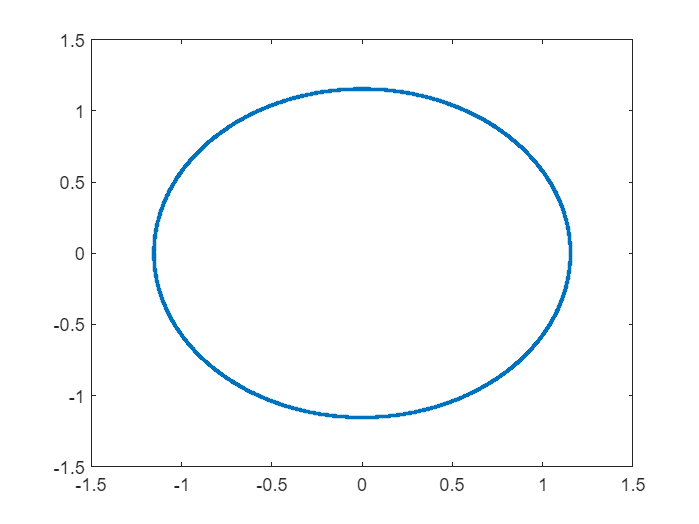

figure()
plot(p_noisy,q_noisy, '.')

Ruido

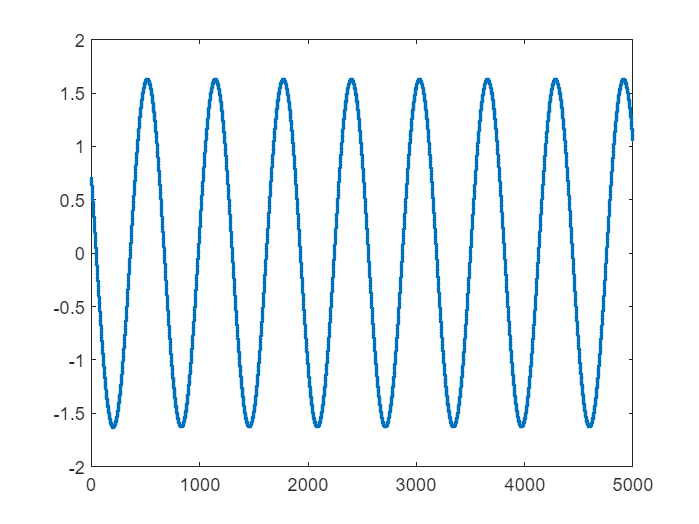

figure
plot(dq, '.')

Guardar datos

output = H_concatenado;
p = p_concatenado;
q = q_concatenado;
dp = dp_concatenado;
dq = dq_concatenado;
save('mass_spring', 'p','q','dp','dq', 'output')